addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')

% Configuration file was changed on xlmcon and then files were processed
% using Leah's processing pipeline 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')

% Uncorrected casts, Calibartion SOC and E term, no hysteresis correction 
cast07_nohyst = readSBScnv( 'uar69-01_007_nohystabcdef.cnv' );
cast08_nohyst = readSBScnv( 'uar69-01_008_nohystabcdef.cnv' );
cast09_nohyst = readSBScnv( 'uar69-01_009_nohystabcdef.cnv' );
cast10_nohyst = readSBScnv( 'uar69-01_010_nohystabcdef.cnv' );
cast11_nohyst = readSBScnv( 'uar69-01_011_nohystabcdef.cnv' );
cast12_nohyst = readSBScnv( 'uar69-01_012_nohystabcdef.cnv' );
cast13_nohyst = readSBScnv( 'uar69-01_013_nohystabcdef.cnv' );
cast14_nohyst = readSBScnv( 'uar69-01_014_nohystabcdef.cnv' );
cast16_nohyst = readSBScnv( 'uar69-01_016_nohystabcdef.cnv' );
cast17_nohyst = readSBScnv( 'uar69-01_017_nohystabcdef.cnv' );
cast18_nohyst = readSBScnv( 'uar69-01_018_nohystabcdef.cnv' );
cast19_nohyst = readSBScnv( 'uar69-01_019_nohystabcdef.cnv' );
cast20_nohyst = readSBScnv( 'uar69-01_020_nohystabcdef.cnv' );
cast21_nohyst = readSBScnv( 'uar69-01_021_nohystabcdef.cnv' );
cast22_nohyst = readSBScnv( 'uar69-01_022_nohystabcdef.cnv' );
cast23_nohyst = readSBScnv( 'uar69-01_023_nohystabcdef.cnv' );

% Uncorrected casts, Calibartion SOC and E term, with hysteresis correction 
cast07_hyst = readSBScnv( 'uar69-01_007_hystabcdef.cnv' );
cast08_hyst = readSBScnv( 'uar69-01_008_hystabcdef.cnv' );
cast09_hyst = readSBScnv( 'uar69-01_009_hystabcdef.cnv' );
cast10_hyst = readSBScnv( 'uar69-01_010_hystabcdef.cnv' );
cast11_hyst = readSBScnv( 'uar69-01_011_hystabcdef.cnv' );
cast12_hyst = readSBScnv( 'uar69-01_012_hystabcdef.cnv' );
cast13_hyst = readSBScnv( 'uar69-01_013_hystabcdef.cnv' );
cast14_hyst = readSBScnv( 'uar69-01_014_hystabcdef.cnv' );
cast15_hyst = readSBScnv( 'uar69-01_015_hystabcdef.cnv' );
cast16_hyst = readSBScnv( 'uar69-01_016_hystabcdef.cnv' );
cast17_hyst = readSBScnv( 'uar69-01_017_hystabcdef.cnv' );
cast18_hyst = readSBScnv( 'uar69-01_018_hystabcdef.cnv' );
cast19_hyst = readSBScnv( 'uar69-01_019_hystabcdef.cnv' );
cast20_hyst = readSBScnv( 'uar69-01_020_hystabcdef.cnv' );
cast21_hyst = readSBScnv( 'uar69-01_021_hystabcdef.cnv' );
cast22_hyst = readSBScnv( 'uar69-01_022_hystabcdef.cnv' );
cast23_hyst = readSBScnv( 'uar69-01_023_hystabcdef.cnv' );

% Casts with corrected SOC, E term and hysteresis 
cast07 = readSBScnv( 'uar69-01_007_KFabcdef.cnv' );
cast08 = readSBScnv( 'uar69-01_008_KFabcdef.cnv' );
cast09 = readSBScnv( 'uar69-01_009_KFabcdef.cnv' );
cast10 = readSBScnv( 'uar69-01_010_KFabcdef.cnv' );
cast11 = readSBScnv( 'uar69-01_011_KFabcdef.cnv' );
cast12 = readSBScnv( 'uar69-01_012_KFabcdef.cnv' );
cast13 = readSBScnv( 'uar69-01_013_KFabcdef.cnv' );
cast14 = readSBScnv( 'uar69-01_014_KFabcdef.cnv' );
cast16 = readSBScnv( 'uar69-01_016_KFabcdef.cnv' );
cast17 = readSBScnv( 'uar69-01_017_KFabcdef.cnv' );
cast18 = readSBScnv( 'uar69-01_018_KFabcdef.cnv' );
cast19 = readSBScnv( 'uar69-01_019_KFabcdef.cnv' );
cast20 = readSBScnv( 'uar69-01_020_KFabcdef.cnv' );
cast21 = readSBScnv( 'uar69-01_021_KFabcdef.cnv' );
cast22 = readSBScnv( 'uar69-01_022_KFabcdef.cnv' );
cast23 = readSBScnv( 'uar69-01_023_KFabcdef.cnv' );


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')
btl = readtable('Irminger_Sea-09_AR69-01_CTD_Sampling_Summary_KF.xlsx','TextType','string');
btl.Cast = double(btl.Cast); btl.Bottle = double(btl.Bottle);
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);
btlsum13 = btl(btl.Cast == 13,:);
btlsum14 = btl(btl.Cast == 14,:);
btlsum16 = btl(btl.Cast == 16,:);
btlsum17 = btl(btl.Cast == 17,:);
btlsum18 = btl(btl.Cast == 18,:);
btlsum19 = btl(btl.Cast == 19,:);
btlsum20 = btl(btl.Cast == 20,:);
btlsum21 = btl(btl.Cast == 21,:);


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year9')

btl07_hyst = readtable('ar69-01_007_hyst.csv','TextType','string');

btl08_hyst = readtable('ar69-01_008_hyst.csv','TextType','string');

btl09_hyst = readtable('ar69-01_009_hyst.csv','TextType','string');

btl10_hyst = readtable('ar69-01_010_hyst.csv','TextType','string');

btl11_hyst = readtable('ar69-01_011_hyst.csv','TextType','string');

btl12_hyst = readtable('ar69-01_012_hyst.csv','TextType','string');

btl13_hyst = readtable('ar69-01_013_hyst.csv','TextType','string');

btl14_hyst = readtable('ar69-01_014_hyst.csv','TextType','string');

btl16_hyst = readtable('ar69-01_016_hyst.csv','TextType','string');

btl17_hyst = readtable('ar69-01_017_hyst.csv','TextType','string');

btl18_hyst = readtable('ar69-01_018_hyst.csv','TextType','string');

btl19_hyst = readtable('ar69-01_019_hyst.csv','TextType','string');

btl20_hyst = readtable('ar69-01_020_hyst.csv','TextType','string');

btl21_hyst = readtable('ar69-01_021_hyst.csv','TextType','string');


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year9')

btl07_nohyst = readtable('ar69-01_007_nohyst.csv','TextType','string');

btl08_nohyst = readtable('ar69-01_008_nohyst.csv','TextType','string');

btl09_nohyst = readtable('ar69-01_009_nohyst.csv','TextType','string');

btl10_nohyst = readtable('ar69-01_010_nohyst.csv','TextType','string');

btl11_nohyst = readtable('ar69-01_011_nohyst.csv','TextType','string');

btl12_nohyst = readtable('ar69-01_012_nohyst.csv','TextType','string');

btl13_nohyst = readtable('ar69-01_013_nohyst.csv','TextType','string');

btl14_nohyst = readtable('ar69-01_014_nohyst.csv','TextType','string');

btl16_nohyst = readtable('ar69-01_016_nohyst.csv','TextType','string');

btl17_nohyst = readtable('ar69-01_017_nohyst.csv','TextType','string');

btl18_nohyst = readtable('ar69-01_018_nohyst.csv','TextType','string');

btl19_nohyst = readtable('ar69-01_019_nohyst.csv','TextType','string');

btl20_nohyst = readtable('ar69-01_020_nohyst.csv','TextType','string');

btl21_nohyst = readtable('ar69-01_021_nohyst.csv','TextType','string');


% Join tables 
btlsum07 = join(btl07_nohyst,btlsum07,'Keys',"Bottle");
btlsum08 = join(btl08_nohyst,btlsum08,'Keys',"Bottle");
btlsum09 = join(btl09_nohyst,btlsum09,'Keys',"Bottle");
btlsum10 = join(btl10_nohyst,btlsum10,'Keys',"Bottle");
btlsum11 = join(btl11_nohyst,btlsum11,'Keys',"Bottle");
btlsum12 = join(btl12_nohyst,btlsum12,'Keys',"Bottle");
btlsum13 = join(btl13_nohyst,btlsum13,'Keys',"Bottle");
btlsum14 = join(btl14_nohyst,btlsum14,'Keys',"Bottle");
btlsum16 = join(btl16_nohyst,btlsum16,'Keys',"Bottle");
btlsum17 = join(btl17_nohyst,btlsum17,'Keys',"Bottle");
btlsum18 = join(btl18_nohyst,btlsum18,'Keys',"Bottle");
btlsum19 = join(btl19_nohyst,btlsum19,'Keys',"Bottle");
btlsum20 = join(btl20_nohyst,btlsum20,'Keys',"Bottle");
btlsum21 = join(btl21_nohyst,btlsum21,'Keys',"Bottle");


btlsum_nohyst = [btlsum07; btlsum08; btlsum09; btlsum10; btlsum11; btlsum12; btlsum13;...
    btlsum14; btlsum16; btlsum17; btlsum18; btlsum19; btlsum20; btlsum21];

cal.SOC = double(4.46780e-001);
cal.VOFFSET = double(-5.08600e-001);
cal.A = double(-5.00190e-003);
cal.B = double(2.51320e-004);
cal.C = double(-3.59380e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.22000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '1960';
cal.OCALDATE = '31-Jul-21';
cal.E2 = 0.0384;

H = [-0.033, 5000, 1450]; % Default 

cast07_hyst.pcorr = exp((cal.E*cast07_hyst.pm)./(cast07_hyst.t090C + 273.15));
cast07_hyst.pcorr2 = exp((cal.E2*cast07_hyst.pm)./(cast07_hyst.t090C + 273.15));
cast07_hyst.DOmLL = cast07_hyst.sbeox0mL_L./cast07_hyst.pcorr.*cast07_hyst.pcorr2; 

cast08_hyst.pcorr = exp((cal.E*cast08_hyst.pm)./(cast08_hyst.t090C + 273.15));
cast08_hyst.pcorr2 = exp((cal.E2*cast08_hyst.pm)./(cast08_hyst.t090C + 273.15));
cast08_hyst.DOmLL = cast08_hyst.sbeox0mL_L./cast08_hyst.pcorr.*cast08_hyst.pcorr2; 

cast09_hyst.pcorr = exp((cal.E*cast09_hyst.pm)./(cast09_hyst.t090C + 273.15));
cast09_hyst.pcorr2 = exp((cal.E2*cast09_hyst.pm)./(cast09_hyst.t090C + 273.15));
cast09_hyst.DOmLL = cast09_hyst.sbeox0mL_L./cast09_hyst.pcorr.*cast09_hyst.pcorr2; 

cast10_hyst.pcorr = exp((cal.E*cast10_hyst.pm)./(cast10_hyst.t090C + 273.15));
cast10_hyst.pcorr2 = exp((cal.E2*cast10_hyst.pm)./(cast10_hyst.t090C + 273.15));
cast10_hyst.DOmLL = cast10_hyst.sbeox0mL_L./cast10_hyst.pcorr.*cast10_hyst.pcorr2; 

cast11_hyst.pcorr = exp((cal.E*cast11_hyst.pm)./(cast11_hyst.t090C + 273.15));
cast11_hyst.pcorr2 = exp((cal.E2*cast11_hyst.pm)./(cast11_hyst.t090C + 273.15));
cast11_hyst.DOmLL = cast11_hyst.sbeox0mL_L./cast11_hyst.pcorr.*cast11_hyst.pcorr2; 

cast12_hyst.pcorr = exp((cal.E*cast12_hyst.pm)./(cast12_hyst.t090C + 273.15));
cast12_hyst.pcorr2 = exp((cal.E2*cast12_hyst.pm)./(cast12_hyst.t090C + 273.15));
cast12_hyst.DOmLL = cast12_hyst.sbeox0mL_L./cast12_hyst.pcorr.*cast12_hyst.pcorr2; 

cast13_hyst.pcorr = exp((cal.E*cast13_hyst.pm)./(cast13_hyst.t090C + 273.15));
cast13_hyst.pcorr2 = exp((cal.E2*cast13_hyst.pm)./(cast13_hyst.t090C + 273.15));
cast13_hyst.DOmLL = cast13_hyst.sbeox0mL_L./cast13_hyst.pcorr.*cast13_hyst.pcorr2; 

cast14_hyst.pcorr = exp((cal.E*cast14_hyst.pm)./(cast14_hyst.t090C + 273.15));
cast14_hyst.pcorr2 = exp((cal.E2*cast14_hyst.pm)./(cast14_hyst.t090C + 273.15));
cast14_hyst.DOmLL = cast14_hyst.sbeox0mL_L./cast14_hyst.pcorr.*cast14_hyst.pcorr2; 

cast16_hyst.pcorr = exp((cal.E*cast16_hyst.pm)./(cast16_hyst.t090C + 273.15));
cast16_hyst.pcorr2 = exp((cal.E2*cast16_hyst.pm)./(cast16_hyst.t090C + 273.15));
cast16_hyst.DOmLL = cast16_hyst.sbeox0mL_L./cast16_hyst.pcorr.*cast16_hyst.pcorr2; 

cast17_hyst.pcorr = exp((cal.E*cast17_hyst.pm)./(cast17_hyst.t090C + 273.15));
cast17_hyst.pcorr2 = exp((cal.E2*cast17_hyst.pm)./(cast17_hyst.t090C + 273.15));
cast17_hyst.DOmLL = cast17_hyst.sbeox0mL_L./cast17_hyst.pcorr.*cast17_hyst.pcorr2; 

cast18_hyst.pcorr = exp((cal.E*cast18_hyst.pm)./(cast18_hyst.t090C + 273.15));
cast18_hyst.pcorr2 = exp((cal.E2*cast18_hyst.pm)./(cast18_hyst.t090C + 273.15));
cast18_hyst.DOmLL = cast18_hyst.sbeox0mL_L./cast18_hyst.pcorr.*cast18_hyst.pcorr2; 

cast19_hyst.pcorr = exp((cal.E*cast19_hyst.pm)./(cast19_hyst.t090C + 273.15));
cast19_hyst.pcorr2 = exp((cal.E2*cast19_hyst.pm)./(cast19_hyst.t090C + 273.15));
cast19_hyst.DOmLL = cast19_hyst.sbeox0mL_L./cast19_hyst.pcorr.*cast19_hyst.pcorr2; 

cast20_hyst.pcorr = exp((cal.E*cast20_hyst.pm)./(cast20_hyst.t090C + 273.15));
cast20_hyst.pcorr2 = exp((cal.E2*cast20_hyst.pm)./(cast20_hyst.t090C + 273.15));
cast20_hyst.DOmLL = cast20_hyst.sbeox0mL_L./cast20_hyst.pcorr.*cast20_hyst.pcorr2; 

cast21_hyst.pcorr = exp((cal.E*cast21_hyst.pm)./(cast21_hyst.t090C + 273.15));
cast21_hyst.pcorr2 = exp((cal.E2*cast21_hyst.pm)./(cast21_hyst.t090C + 273.15));
cast21_hyst.DOmLL = cast21_hyst.sbeox0mL_L./cast21_hyst.pcorr.*cast21_hyst.pcorr2; 

cast22_hyst.pcorr = exp((cal.E*cast22_hyst.pm)./(cast22_hyst.t090C + 273.15));
cast22_hyst.pcorr2 = exp((cal.E2*cast22_hyst.pm)./(cast22_hyst.t090C + 273.15));
cast22_hyst.DOmLL = cast22_hyst.sbeox0mL_L./cast22_hyst.pcorr.*cast22_hyst.pcorr2; 

cast23_hyst.pcorr = exp((cal.E*cast23_hyst.pm)./(cast23_hyst.t090C + 273.15));
cast23_hyst.pcorr2 = exp((cal.E2*cast23_hyst.pm)./(cast23_hyst.t090C + 273.15));
cast23_hyst.DOmLL = cast23_hyst.sbeox0mL_L./cast23_hyst.pcorr.*cast23_hyst.pcorr2; 

gain = btlsum_nohyst.Winkler_mLL./btlsum_nohyst.Sbeox0ML_L

gain =     1.0781
    1.0946
       NaN
       NaN
       NaN
       NaN
    1.0804
    1.0754
    1.0673
    1.0674


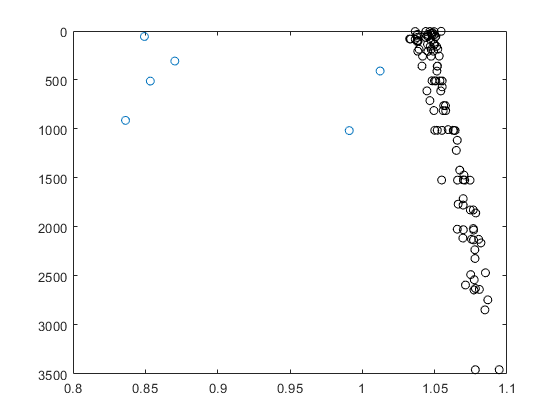

gain(gain < 1.02) = NaN;

figure
plot(btlsum_nohyst.Winkler_mLL./btlsum_nohyst.Sbeox0ML_L,btlsum_nohyst.PrDM,'o')
hold on
plot(gain,btlsum_nohyst.PrDM,'ok')
hold on
axis ij


Gain = nanmean(gain);
Gain_std = nanstd(gain);
disp(['Gain = ' num2str(Gain) '+/- ' num2str(Gain_std)])

Gain = 1.0577+/- 0.014402


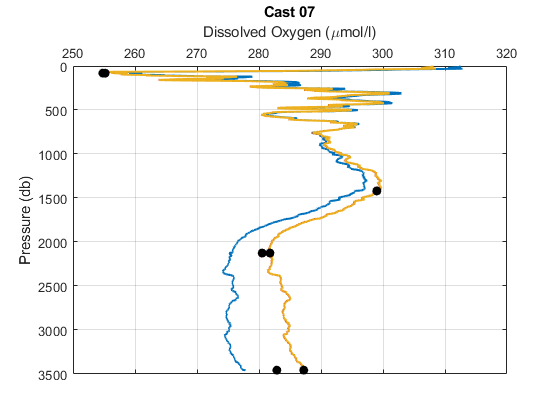

SOC2 = 1.0391;
SOC2 = 1.0384;
figure
plot(cast07_nohyst.sbeox0mL_L*Gain*44.661,cast07_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast07_hyst.DOmLL*SOC2*44.661,cast07_hyst.pm,'Linewidth',1.5)
plot(cast07.sbeox0mL_L*44.661,cast07.pm,'Linewidth',1.5)
plot(btlsum07.Winkler_mLL*44.661,btlsum07.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 07')

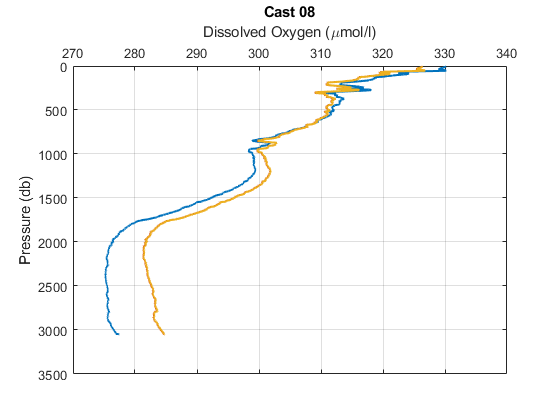


figure
plot(cast08_nohyst.sbeox0mL_L*Gain*44.661,cast08_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast08_hyst.DOmLL*SOC2*44.661,cast08_hyst.pm,'Linewidth',1.5)
plot(cast08.sbeox0mL_L*44.661,cast08.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 08')

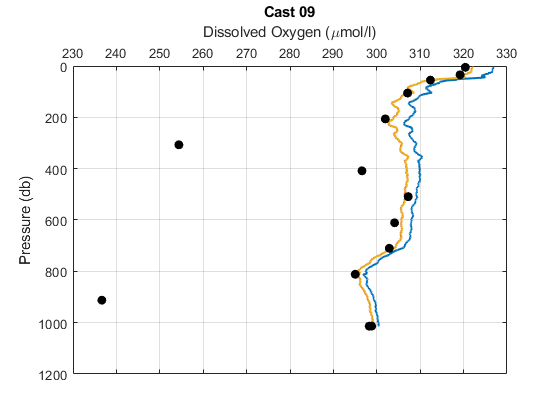


figure
plot(cast09_nohyst.sbeox0mL_L*Gain*44.661,cast09_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast09_hyst.DOmLL*SOC2*44.661,cast09_hyst.pm,'Linewidth',1.5)
plot(cast09.sbeox0mL_L*44.661,cast09.pm,'Linewidth',1.5)
plot(btlsum09.Winkler_mLL*44.661,btlsum09.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 09')

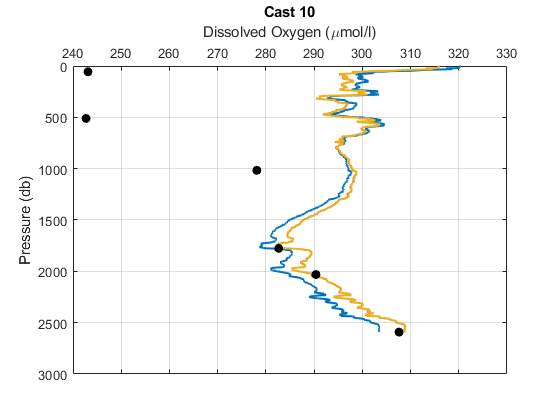


figure
plot(cast10_nohyst.sbeox0mL_L*Gain*44.661,cast10_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast10_hyst.DOmLL*SOC2*44.661,cast10_hyst.pm,'Linewidth',1.5)
plot(cast10.sbeox0mL_L*44.661,cast10.pm,'Linewidth',1.5)
plot(btlsum10.Winkler_mLL*44.661,btlsum10.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 10')

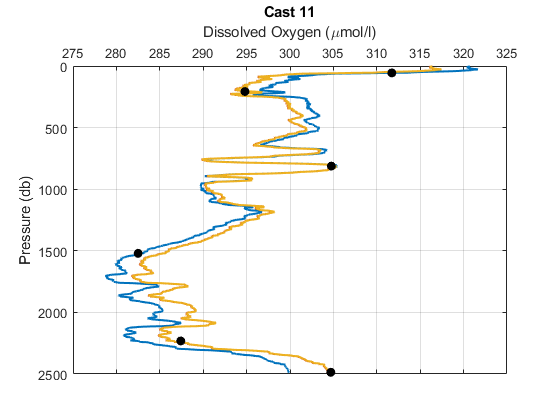


figure
plot(cast11_nohyst.sbeox0mL_L*Gain*44.661,cast11_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast11_hyst.DOmLL*SOC2*44.661,cast11_hyst.pm,'Linewidth',1.5)
plot(cast11.sbeox0mL_L*44.661,cast11.pm,'Linewidth',1.5)
plot(btlsum11.Winkler_mLL*44.661,btlsum11.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 11')

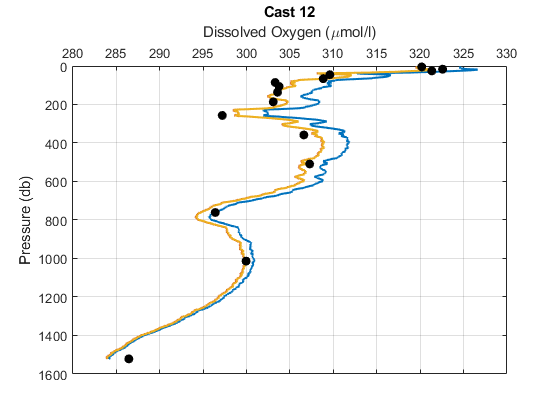


figure
plot(cast12_nohyst.sbeox0mL_L*Gain*44.661,cast12_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast12_hyst.DOmLL*SOC2*44.661,cast12_hyst.pm,'Linewidth',1.5)
plot(cast12.sbeox0mL_L*44.661,cast12.pm,'Linewidth',1.5)
plot(btlsum12.Winkler_mLL*44.661,btlsum12.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 12')

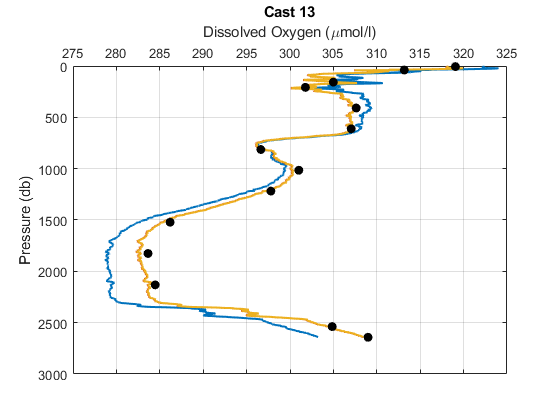


figure
plot(cast13_nohyst.sbeox0mL_L*Gain*44.661,cast13_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast13_hyst.DOmLL*SOC2*44.661,cast13_hyst.pm,'Linewidth',1.5)
plot(cast13.sbeox0mL_L*44.661,cast13.pm,'Linewidth',1.5)
plot(btlsum13.Winkler_mLL*44.661,btlsum13.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 13')

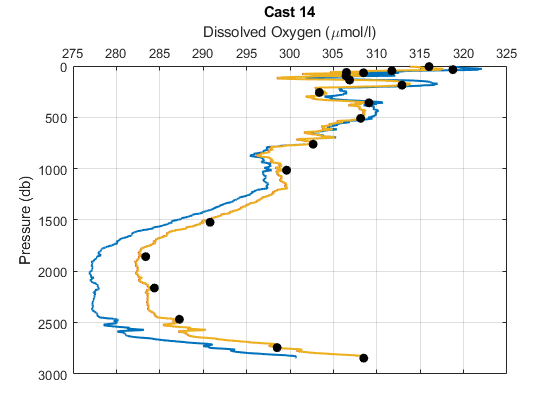


figure
plot(cast14_nohyst.sbeox0mL_L*Gain*44.661,cast14_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast14_hyst.DOmLL*SOC2*44.661,cast14_hyst.pm,'Linewidth',1.5)
plot(cast14.sbeox0mL_L*44.661,cast14.pm,'Linewidth',1.5)
plot(btlsum14.Winkler_mLL*44.661,btlsum14.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 14')

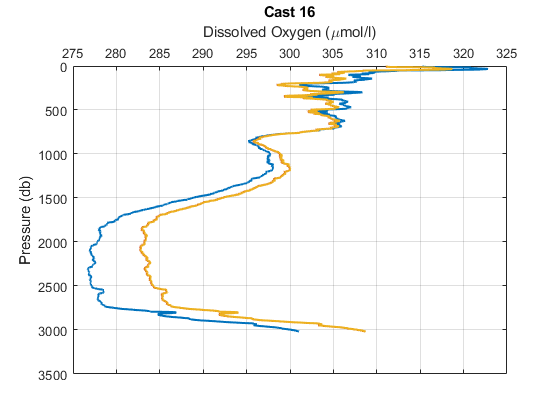


figure
plot(cast16_nohyst.sbeox0mL_L*Gain*44.661,cast16_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast16_hyst.DOmLL*SOC2*44.661,cast16_hyst.pm,'Linewidth',1.5)
plot(cast16.sbeox0mL_L*44.661,cast16.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 16')

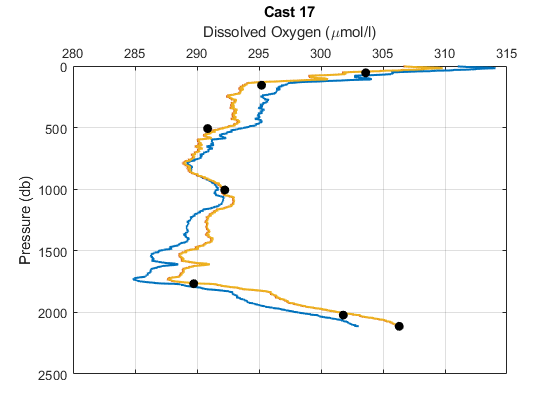


figure
plot(cast17_nohyst.sbeox0mL_L*Gain*44.661,cast17_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast17_hyst.DOmLL*SOC2*44.661,cast17_hyst.pm,'Linewidth',1.5)
plot(cast17.sbeox0mL_L*44.661,cast17.pm,'Linewidth',1.5)
plot(btlsum17.Winkler_mLL*44.661,btlsum17.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 17')

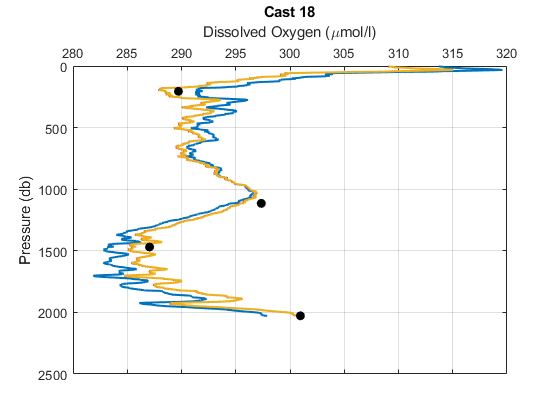


figure
plot(cast18_nohyst.sbeox0mL_L*Gain*44.661,cast18_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast18_hyst.DOmLL*SOC2*44.661,cast18_hyst.pm,'Linewidth',1.5)
plot(cast18.sbeox0mL_L*44.661,cast18.pm,'Linewidth',1.5)
plot(btlsum18.Winkler_mLL*44.661,btlsum18.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 18')

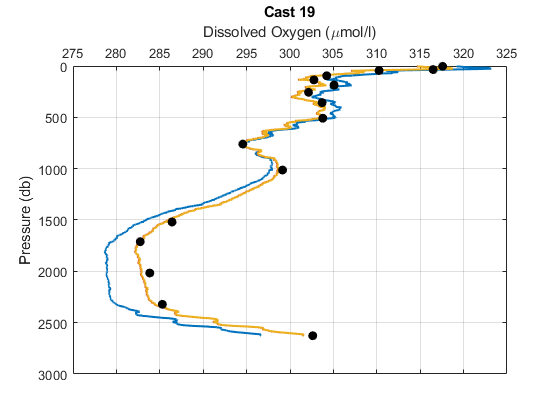


figure
plot(cast19_nohyst.sbeox0mL_L*Gain*44.661,cast19_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast19_hyst.DOmLL*SOC2*44.661,cast19_hyst.pm,'Linewidth',1.5)
plot(cast19.sbeox0mL_L*44.661,cast19.pm,'Linewidth',1.5)
plot(btlsum19.Winkler_mLL*44.661,btlsum19.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 19')

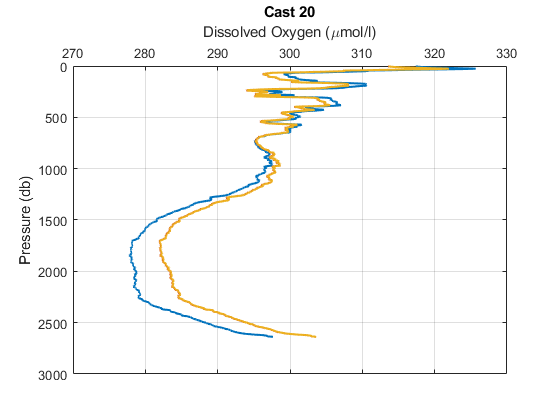


figure
plot(cast20_nohyst.sbeox0mL_L*Gain*44.661,cast20_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast20_hyst.DOmLL*SOC2*44.661,cast20_hyst.pm,'Linewidth',1.5)
plot(cast20.sbeox0mL_L*44.661,cast20.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 20')

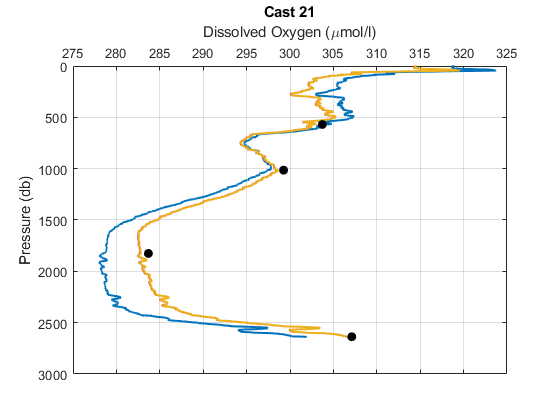


figure
plot(cast21_nohyst.sbeox0mL_L*Gain*44.661,cast21_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast21_hyst.DOmLL*SOC2*44.661,cast21_hyst.pm,'Linewidth',1.5)
plot(cast21.sbeox0mL_L*44.661,cast21.pm,'Linewidth',1.5)
plot(btlsum21.Winkler_mLL*44.661,btlsum21.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 21')

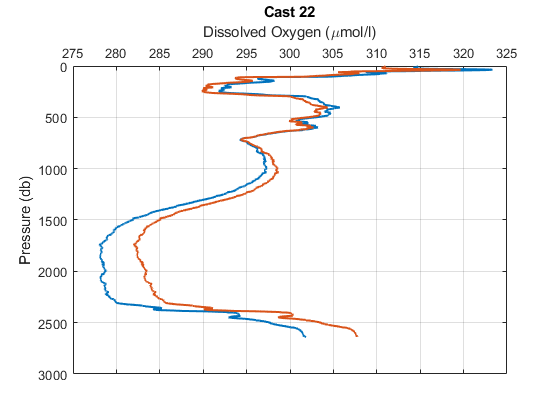


figure
plot(cast22_nohyst.sbeox0mL_L*Gain*44.661,cast22_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast22.sbeox0mL_L*44.661,cast22.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 22')

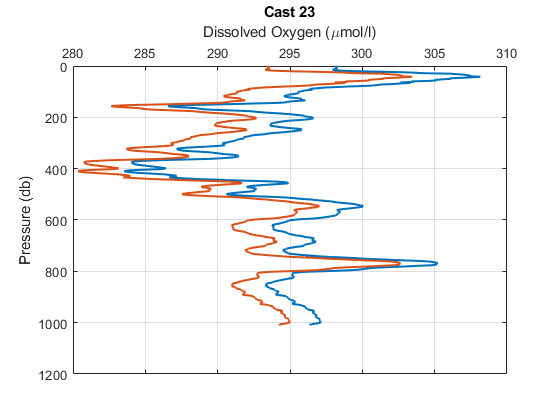


figure
plot(cast23_nohyst.sbeox0mL_L*Gain*44.661,cast23_nohyst.pm,'Linewidth',1.5)
hold on
plot(cast23.sbeox0mL_L*44.661,cast23.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 23')